# indentPlot

This live script is continuation of calciumPlot.mlx and applied to the indentation stimuli

#### Load the indenter stimulation file

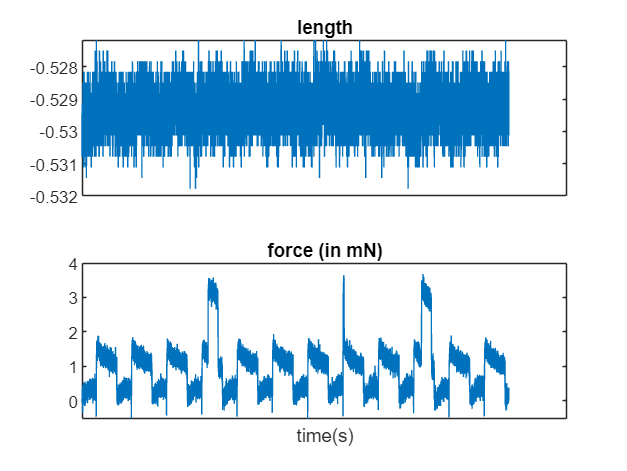

folderNameTemp = strsplit(path,filesep);
folderName = folderNameTemp{end-1};
clear folderNameTemp
[filenameMat,pathMat] = uigetfile('\\research.files.med.harvard.edu\Neurobio\GintyLab\Qi\stimulation\indenter\*.mat',...
    ['select an indentation file for   ', folderName]);

% [filenameMat,pathMat] = uigetfile('C:\Users\Qi_Li\Dropbox (HMS)\LQCalciumImaging\stimulation\indenter\*.mat', ...
%     ['select an indentation file for
load([pathMat,filenameMat])
force = data(:,3);
down = 10;
figure,
tick = floor(numel(force)/Fs/5/10)*10;
% subplot(311),plot(cameraTrigger(1:10:end)),title('Trigger'),
subplot(211),plot(data(1:down:end,2)),title("length");
xticks(tick*Fs/down:tick*Fs/down:numel(force)/down)
xticklabels(strsplit(num2str(tick: tick: floor(numel(force)/Fs))));
subplot(212),plot(data(1:down:end,3)*50),title("force (in mN)");
xticks(tick*Fs/down:tick*Fs/down:numel(force)/down)
xticklabels(strsplit(num2str(tick: tick: floor(numel(force)/Fs))));
xlabel('time(s)')

% plot(force),title("force")
% pbaspect([3 1 1])
% set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);
% nUnit = ceil(length(I)/nSweep);

#### Split the indenter file

% cut out the interSweepInterval and indentIntervalTime, then split the indentation into "nSweep" part
indentOn = baseline + indentTime + decayTime;
indentUnit = length(force) / numSweeps - interSweepInterval * Fs;
indentSubUnit = indentUnit/numel(intensities) - indentIntervalTime * Fs;
if indentSubUnit ~= (indentOn * Fs)
    error ('Something wrong with the indentation format');
end

forceSplitPre = zeros(indentSubUnit,numel(intensities), numSweeps);

for i = 1:numSweeps
    indentStart = length(force) / numSweeps * (i-1) +1;
    indentEnd = indentStart + indentUnit - 1;
    indentBySweep = force(indentStart:indentEnd);
    for j = 1: numel(intensities)
        indentSubStart = indentUnit/ numel(intensities) * (j-1) +1;
        indentSubEnd = indentSubStart + indentSubUnit -1;
        forceSplitPre(:, j, i) = indentBySweep(indentSubStart:indentSubEnd);
    end
end
forceSplit = reshape(forceSplitPre, indentSubUnit * numel(intensities), numSweeps);
clear indentUnit indentSubUnit indentStart indentEnd indentSubStart indentSubEnd forceSplitPre i j

####  Align the indentation with response and save the figure

indentAlign(numSweeps,normDeltaF,path,filename,forceSplit);

Unrecognized function or variable 'normDeltaF'.

goodROI = [9, 10, 11];
peak_thresh = 0.07;
forceSweep = intensities * 50;
[~, ROIindex] = ismember(goodROI, responseROI0);
cunit = indentOn * fps;
threshold = zeros(numel(goodROI), numSweeps);
Amp = zeros(numel(goodROI), numel(intensities), numSweeps);
splitTrace = zeros(numel(goodROI), cunit, numel(intensities), numSweeps);
for i = 1: numel(goodROI)
    goodTraceTemp = normDeltaF(:, goodROI(i));
    splitTraceTemp = reshape(goodTraceTemp, [cunit, numel(intensities), numSweeps]);
    for j = 1:numel(intensities)
        for k = 1:numSweeps
            [pks,locs] = findpeaks(splitTraceTemp(:, j, k),'MinPeakProminence', peak_thresh);
            if locs  %if peak exists under certain threshold (peak_thresh)
                locs = locs((baseline * fps < locs)& (locs<(baseline + indentTime + 2)*fps));
                % remove the peaks that are in baseline period
                pks = pks((baseline * fps < locs) & (locs< (baseline + indentTime + 2)* fps));
                Amp(i, j, k) = max(pks);
            end
        end
    end
end

for i = 1:numel(goodROI)
    for k = 1:numSweeps
        indexTemp = find(Amp(i,:,k));
        threshold(i, k) = forceSweep (indexTemp(1));
    end
end

%% inspect the threshold data
figure, bar(threshold), title('response threhold for indentation')
% ylim([0, max(forceSweep)]), 
xlabel('cell'), ylabel('force(mN)')

figure,
set(gcf,'Visible','on')
for i = 1:size(Amp,3)
    subplot(size(Amp,3), 1, i), bar(Amp(:,:,i));
    xlabel('cell'), ylabel('deltaF/F'), title(['Sweep ', num2str(i)]);
    set(gcf, 'Position', [50, 50, 1200, 700])
end

#### save the threshold and Amp into a structure for every mouse

indentResponseName = [path, 'indentResponse.mat'];
if isfile(indentResponseName)
    load(indentResponseName);
else
    indentResponse = struct;
end

indentResponse.threshold.(filename(1:end-4)) = threshold;
indentResponse.Amp.(filename(1:end-4)) = Amp;
indentResponse.goodROI.(filename(1:end-4)) = goodROI;

save(indentResponseName, 'indentResponse');
clear indentResponseName